%% GCN su dataset di volti (Eigenfaces)
% Questo script costruisce un grafo di similarità tra le immagini (Eigenfaces),
% addestra una GCN artigianale (1 layer) e valuta la classificazione.

%% 1) Caricamento e preparazione dati
load('dataset/volti_dataset.mat');   % A, labels
load('results/mean_face.mat');
load('results/svd_data.mat');        % U

k = 100;
U_k = U(:, 1:k);
A_centered = A - mean_face;
X = (U_k' * A_centered)';   % [n_samples x k]
num_samples = size(X,1);
num_classes = max(labels);

% One-hot encoding
Y = zeros(num_classes, num_samples);
for i = 1:num_samples
    Y(labels(i), i) = 1;
end

%% 2) COSTRUISCI IL GRAFO: matrice di adiacenza A_hat
K = 10;  % Numero vicini
A = zeros(num_samples, num_samples);
for i = 1:num_samples
    dists = sum((X - X(i,:)).^2, 2);
    [~, idx] = sort(dists);
    neighbors = idx(2:K+1);   % Esclude sé stesso
    A(i, neighbors) = 1;
end
A = max(A, A');  % Simmetrica
A_hat = A + eye(num_samples);

% Normalizza (A_hat): D^(-1/2) * A_hat * D^(-1/2)
D = diag(sum(A_hat, 2));
A_hat_norm = D^(-0.5) * A_hat * D^(-0.5);

%% 3) Split train/test
rng(0);
perm = randperm(num_samples);
split = round(0.8 * num_samples);
train_idx = perm(1:split);
test_idx  = perm(split+1:end);

X_train = X(train_idx, :);
Y_train = Y(:, train_idx);

X_test = X(test_idx, :);
Y_test = Y(:, test_idx);

A_train = A_hat_norm(train_idx, train_idx);

%% 4) Addestramento GCN
epochs        = 100;
learning_rate = 0.01;
fprintf('--- Training GCN ---\n');

--- Training GCN ---


[W, loss_hist, acc_hist] = gcn_train(X_train, Y_train, A_train, epochs, learning_rate);

[GCN] Epoca   1/100 — Loss: 27.0956 — Acc: 1.83%
[GCN] Epoca  10/100 — Loss: 9.1062 — Acc: 66.77%
[GCN] Epoca  20/100 — Loss: 3.7263 — Acc: 85.37%
[GCN] Epoca  30/100 — Loss: 3.0108 — Acc: 89.02%
[GCN] Epoca  40/100 — Loss: 1.5163 — Acc: 94.51%
[GCN] Epoca  50/100 — Loss: 1.1246 — Acc: 95.73%
[GCN] Epoca  60/100 — Loss: 1.0109 — Acc: 96.34%
[GCN] Epoca  70/100 — Loss: 1.0002 — Acc: 96.04%
[GCN] Epoca  80/100 — Loss: 0.8505 — Acc: 96.65%
[GCN] Epoca  90/100 — Loss: 1.0673 — Acc: 95.73%
[GCN] Epoca 100/100 — Loss: 0.5897 — Acc: 97.87%


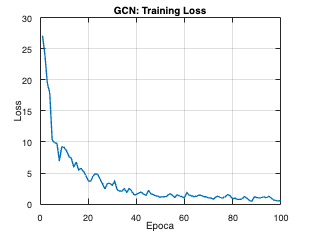


%% 5) Plot di loss e accuracy
figure('Name','GCN: Loss & Accuracy','NumberTitle','off');

plot(1:epochs, loss_hist, 'LineWidth',1.5);
xlabel('Epoca'); ylabel('Loss');
title('GCN: Training Loss'); grid on;

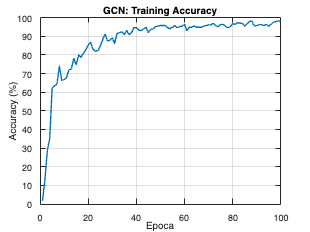


plot(1:epochs, acc_hist, 'LineWidth',1.5);
xlabel('Epoca'); ylabel('Accuracy (%)');
title('GCN: Training Accuracy'); grid on;


%% 6) Valutazione su test set (resta invariata)
A_test = A_hat_norm(test_idx, train_idx);
Z_test = (A_test * X_train) * W;
Z_test = Z_test';
Z_test = Z_test - max(Z_test,[],1);
expZ   = exp(Z_test);
A2     = expZ ./ sum(expZ,1);
[~, y_pred] = max(A2,[],1);
[~, y_true] = max(Y(:, test_idx), [], 1);
acc_test = mean(y_pred' == y_true') * 100;
fprintf('Test accuracy (GCN): %.2f%%\n', acc_test);

Test accuracy (GCN): 81.71%




fprintf('>>> Tempo totale: %.2f s\n', toc);

>>> Tempo totale: 241.25 s
